# Trebuchet Model Introduction

Jaiden King | 10/26/2025

This document introduces an onboarding developer to the overall Trebuchet project, the mathematical model, and the code implementing the model. 

This MATLAB live script is intended to be viewed with code hidden.

## Project Overview

The main goal of the project is to design and build a trebuchet. A constraint on that goal is that I want to engineer the system well such that it works properly the first time. There are many different parameters to tweak when designing a trebuchet, and instead of guessing/checking/iterating with physical prototypes I am instead developing a mathematical model to predict the behavior. Having this model will also allow me to optimize the design with a simple machine learning algorithm, rather than trying to optimize it myself. This is important due to my lack of intuition regarding the problem. 

A unique design choice for this trebuchet is the energy source. Typically, a trebuchet stores energy in a counterweight. If a missile launcher uses springs, it's often designed more like a catapult or ballista. I plan to have energy stored in a spring, while still taking advantage of the sling mechanics of a trebuchet. 

## Math

The math serves 2 purposes:

- Control dynamics. We want the ability to reliably dictate the manner in which the projectile is launched. Typically this means launching at a 45° angle and efficiently spending the spring energy. 

- Load requirements. We want to know what forces our components will be experiencing so we can design a sturdy structure without over-building.

- Design optimization. In order to optimize the design, we need a function that can rate the performance of the design.

To have any control over the dynamics, we'll need to derive the equations of motion for the system. With the equations of motion, we can work out any additional forces we're in for analyzing loads. 

### The Model

The current (10/26/2025) model is a very simple approximation. It will be made more accurate once I'm confident in the software infrastructure. 

The system is modeled as a variation on the classic double pendulum problem. The first pendulum is the arm of the trebuchet rigidly rotating about a fixed point. The second pendulum is the projectile connected with a rope to the end of the trebuchet arm. The one variation is the addition of a spring, which is connected to the arm. 

We will be using the Lagrangian approach for deriving the equations of motion. The Lagrangian $L$ of the system is given by the equation


$$L=T-V$$


where $T$ is the kinetic energy of the system and $V$ is the potential energy. This means we only need to specify the energies of the bodies at first (rather than considering forces).

For our coordinate system, I am choosing generalized coordinates $\theta_1(t)$ for the angle of the arm and $\theta_2(t)$ for the angle of the projectile rope, each with respect to the +x direction. The +y direction will be up and +z will be pointing out of the screen such that $\dot\theta>0$ is a counter clockwise rotation. In this coordinate system, the trebuchet will generally have a positive rotational rate and the projectile will be thrown in the -x direction. 

#### Kinematic Constraints

Deriving the energy of the system starts with specifying the constraints on the positions of the bodies. We will write the cartesian coordinate components of each body in terms of the generalized coordiantes. 

displayCase = 2;
DispSysVar(sysvar.x_1, displayCase);

$$x_{1}=l_{1}\,\cos\left(\theta_{1}\right)$$

DispSysVar(sysvar.y_1, displayCase);

$$y_{1}=l_{1}\,\sin\left(\theta_{1}\right)$$

DispSysVar(sysvar.x_2, displayCase);

$$x_{2}=x_{1}+l_{2}\,\cos\left(\theta_{2}\right)$$

DispSysVar(sysvar.y_2, displayCase);

$$y_{2}=y_{1}+l_{2}\,\sin\left(\theta_{2}\right)$$

% Spring should be shown here too

#### Velocity

We then need the velocities, which can be found by taking the time derivative of the position components. In the future the code should do this step automatically, but because I've manually specified the expressions I'll show them here as well.

DispSysVar(sysvar.x_dot_1, displayCase);

$${\dot{x}}_{1}=-l_{1}\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)$$

DispSysVar(sysvar.y_dot_1, displayCase);

$${\dot{y}}_{1}=l_{1}\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)$$

DispSysVar(sysvar.x_dot_2, displayCase);

$${\dot{x}}_{2}={\dot{x}}_{1}-l_{2}\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right)$$

DispSysVar(sysvar.y_dot_2, displayCase);

$${\dot{y}}_{2}={\dot{y}}_{1}+l_{2}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{2}\right)$$

#### Potential Energy

The potential energy for the two pendulum bodies comes from their heights.

DispSysVar(sysvar.V_1, displayCase);

$$V_{1}=g\,m_{1}\,y_{1}$$

DispSysVar(sysvar.V_2, displayCase);

$$V_{2}=g\,m_{2}\,y_{2}$$

Potential energy in the spring comes from its displacement, which will be derived from the arm angle.

DispSysVar(sysvar.V_3, displayCase);

$$V_{3}=\frac{k\,{\theta_{1}}^{2}}{2}$$

Total system potential energy:

DispSysVar(sysvar.V, 1);

$$\left(V=V_{1}+V_{2}+V_{3}\right)=0.5\,k\,{\theta_{1}}^{2}+g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)+g\,l_{1}\,m_{2}\,\sin\left(\theta_{1}\right)+g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)$$

#### Kinetic Energy

The kinetic energy of each body comes from their velocities. The spring will be treated as massless and therefore has no kinetic energy. 

DispSysVar(sysvar.T_1, displayCase);

$$T_{1}=\frac{m_{1}\,\left({{\dot{x}}_{1}}^{2}+{{\dot{y}}_{1}}^{2}\right)}{2}$$

DispSysVar(sysvar.T_2, displayCase);

$$T_{2}=\frac{m_{2}\,\left({{\dot{x}}_{2}}^{2}+{{\dot{y}}_{2}}^{2}\right)}{2}$$

Total system kinetic energy. The equations will be displayed for completeness, but from this point on they're mainly being symbolically evaluated by the computer and become difficult to follow.

DispSysVar(sysvar.T, 1);

$$\left(T=T_{1}+T_{2}\right)=0.5\,{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}+0.5\,{l_{1}}^{2}\,m_{2}\,{{\dot{\theta }}_{1}}^{2}+0.5\,{l_{2}}^{2}\,m_{2}\,{{\dot{\theta }}_{2}}^{2}+l_{1}\,l_{2}\,m_{2}\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}-1.0\,\theta_{2}\right)$$

#### The Lagrangian

Subtracting the energies to form the Lagrangian might seem odd. We know that energy must be conserved: $T+V=constant$. The Lagrangian subtracts the energies to give an indication of the "balance" of the two energies. 

DispSysVar(sysvar.L, 1);

$$\left(L=T-V\right)=0.5\,{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}-0.5\,k\,{\theta_{1}}^{2}+0.5\,{l_{1}}^{2}\,m_{2}\,{{\dot{\theta }}_{1}}^{2}+0.5\,{l_{2}}^{2}\,m_{2}\,{{\dot{\theta }}_{2}}^{2}-1.0\,g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)-1.0\,g\,l_{1}\,m_{2}\,\sin\left(\theta_{1}\right)-1.0\,g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)+l_{1}\,l_{2}\,m_{2}\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}-1.0\,\theta_{2}\right)$$

To oversimplify the Principle of Least Action, the equations of motion for our system are those that minimize the action $S=\int_{t_0}^{t_f} L\ dt$. Euler and Lagrange showed this to be equivalent to solving the following differential equations


$$\frac{d}{dt}\left(\frac{\partial L}{\partial\dot q_i}\right)=\frac{\partial L}{\partial q_i}$$


where $q_i \in \{\theta_1(t),\ \theta_2(t)\}$ are our generalized coordinates. These derivatives are computed symbolically by MATLAB and are a mess so I won't display them here. 

#### Solving the Differential Equations

The equations of motion might be better described as constraints. We still don't have a value for $\theta_1(t)$ and $\theta_2(t)$. This is the first piece of math that even MATLAB can't do symbolically, so we use a numerical integrator (`ode45` as of 10/26/2025) to get an approximate solution. 

First, we specify numeric values for our system constants. Most of these numbers are arbitrary until we have a learning algorithm. I just want to be able to get a sense if the code and math are working.

% Make sure to run LoadSolution.m
% I think this was made with 20251026-1234-DiffEqnSolution.mat
SysParamDisplayCase = 3;
DispSysVar(sysparam.constants.g, SysParamDisplayCase);

$$g=9.8$$

DispSysVar(sysparam.constants.l_1, SysParamDisplayCase);

$$l_{1}=1.0$$

DispSysVar(sysparam.constants.l_2, SysParamDisplayCase);

$$l_{2}=0.8$$

DispSysVar(sysparam.constants.m_1, SysParamDisplayCase);

$$m_{1}=5.0$$

DispSysVar(sysparam.constants.m_2, SysParamDisplayCase);

$$m_{2}=0.51$$

DispSysVar(sysparam.constants.k, SysParamDisplayCase);

$$k=20.0$$

Next we specify the initial conditions of the differential equations.

DispSysVar(sysparam.init_cond.theta_1_0,     4);

$$\left(\begin{array}{cc} \theta_{1,0}=-120.0 & \mathrm{degrees} \end{array}\right)$$

DispSysVar(sysparam.init_cond.theta_dot_1_0, 4);

$$\left(\begin{array}{cc} {\dot{\theta }}_{1,0}=0.0 & \mathrm{degrees} \end{array}\right)$$

DispSysVar(sysparam.init_cond.theta_2_0,     4);

$$\left(\begin{array}{cc} \theta_{2,0}=-130.0 & \mathrm{degrees} \end{array}\right)$$

DispSysVar(sysparam.init_cond.theta_dot_2_0, 4);

$$\left(\begin{array}{cc} {\dot{\theta }}_{2,0}=0.0 & \mathrm{degrees} \end{array}\right)$$

We can then instruct MATLAB to solve the ODE on our desired time range (0-2s) and it will evaluate as many discrete points as it deems necessary. We can then interpolate between those points to find the function values at an arbitrary time. The result is that we now have a means to evaluate $\theta_1(t),\ \dot\theta_1(t),\ \ddot\theta_1(t),\ \theta_2(t),\ \dot\theta_2(t),\text{ and }\ddot\theta_2(t)$ from which we can compute the values of all other system properties. 

### Visualizing The Results

The easiest plot to interpret is the spatial trajectory. This plot shows the initial starting position, the position at the time of release, and intermediate positions at equally spaced time intervals. The solver doesn't stop computing at release time, so the remainder of the computed trajectory (as if no release occured) is shown as a dashed line.

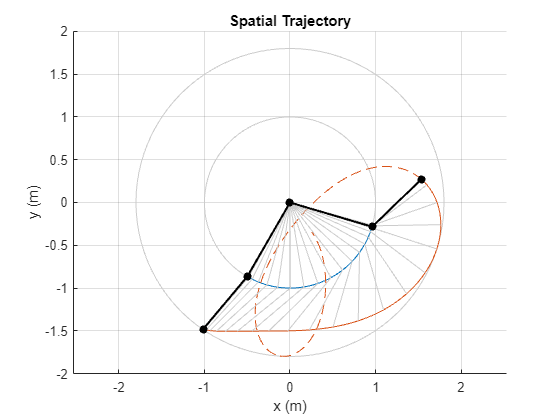

figure();
sub_PlotSpatialTrajectory;
legend off;

We can get a general sense of if the system's behaving right from the spatial plot, but the more quantitatively meaningful plots are the Energy plots. Generally, we're looking for the system to start with a large amount of stored energy (the potential energy of the spring) and have all that energy transfer into the projectile right at the moment of release.  A vertical line on these plots marks the release point. An additional plot of the total system energy is shown for quality control. The total system energy should be exactly conserved (flat line on the plot), but the numerical solution introduces errors. Increasing the solver accuracy is a tradeoff with computation time. As long as the total energy in the system isn't fluctuating a large amount relative to the ranges of the potential and kinetic components, I'll tolerate some error.

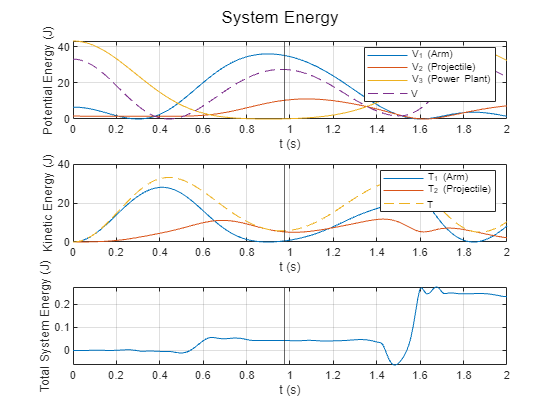

figure();
sub_PlotSystemEnergy;

### Future Work

The next thing to do will be formulating this system as a convex optimization problem. If we let ${\bf x}$ be a vector of the system parameters (such as arm length, rope length, etc.), that would mean defining some cost function $f({\bf x})$ which we want to minimize, a set of inequality constraints $g_i({\bf x}) \le 0$, a set of equality constraints $h_i({\bf x}) = 0$, and a feasible set $C$ for the values of ${\bf x}$.

The math shouldn't be hard for this step. The cost function will likely refer to just the release energy. An inequality constraint would be that the rope tension must stay strictly positive (to avoid going slack). Specifying a feasible set of parameters will be important later (keeping the size reasonable, realistic spring values, etc.) but only needs to be carefully addressed if results start looking unreasonable. 

The hardest part of the optimization will most likely just be making sure the code is clean and well organized. 

Once the optimizer works, I can improve the accuracy of it by replacing the point-mass representation of the arm with a rotating body. I expect rotational inertia to be significant for the arm. 

That would then be a good starting point to begin the CAD work. I can come up with detailed designs based on the optimizer, then plug in the actual values for length and mass etc. back into the simulation and have it re-adjust. That process would be repeated until I have a prototype design ready to fabricate.